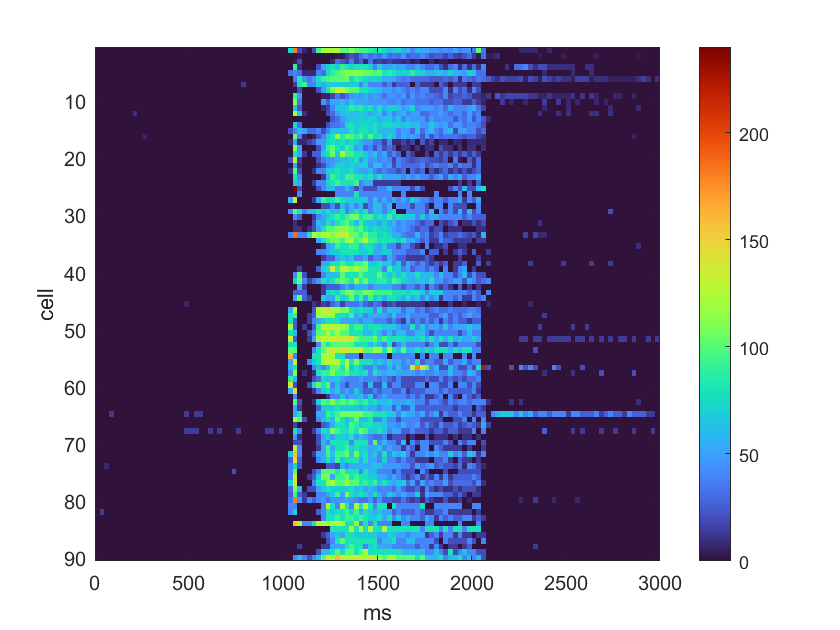

% flash responses - builds heat map and average psth for flash responses from desired cells
cs = grabFromFilter('All Usable DS');
windowTime = 25; %ms
%get names of all cells that meet inclusion criteria

cells = cs(:, 1)';
structs = cs(:, 2)';
%choose which protocols to look at
priorityOrder_1 = {'Flash'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'_ff'; '_all'; 'Extracellular'}; %child field name should be one of these. Priority is in given order
noAnalyses = [];
analysesUsed = {};

psth_full = [];
for i = 1:numel(structs)
    struct_i = structs{i};
    
    if strfind(struct_i.cellID, 'SHOKR33')%don't include these cells
        %continue
    end
    
    analyses = fieldnames(struct_i.Analyses_Completed);
    analysisToUse_1 = findAnalysisToUse(priorityOrder_1, analyses);
    if ~strcmp(analysisToUse_1, 'NoneFound')
        analysisToUse_2 = findAnalysisToUse(priorityOrder_2, fieldnames(struct_i.Analyses_Completed.(analysisToUse_1)));
    else
        analysisToUse_2 = 'NoneFound';
    end

    
    analysesUsed{end + 1} = [analysisToUse_1 '_' analysisToUse_2];
    %grab preferred direction, and vector length
    
    if strcmp(analysisToUse_2, 'NoneFound')
        noAnalyses(end + 1) = i;
        %continue
    end
    
    %grab preferred direction, and vector length
    loc = struct_i.Analyses_Completed.(analysisToUse_1).(analysisToUse_2);
    
    preTime_i = loc.meta.preTime;
    stimTime_i = loc.meta.stimTime;
    tailTime_i = loc.meta.tailTime;
    

    totalTime = preTime_i + stimTime_i + tailTime_i;
    
    if totalTime ~= 3000
        continue
    end
    spikeTimes_i = loc.Analysis_Results.allSpikeTimes;
    
    numBins = numel(0:windowTime:(totalTime-windowTime));
    results_i = zeros(numel(spikeTimes_i), numBins);
    for j = 1:numel(spikeTimes_i)
        s = spikeTimes_i{j};
        psth_j = zeros(1, numBins);
        for k = 0:numBins-1
            spikesInWindow = numel(s(s>k*windowTime & s<(k*windowTime+windowTime)))/(windowTime/1000);
            psth_j(k+1) = spikesInWindow;
        end
        results_i(j, :) = psth_j;
    end
    
    
    if j == 1
        meanResults = results_i;
    else
        meanResults = mean(results_i);
    end
    
    psth_full = [psth_full; meanResults];
            
end
xvals = [windowTime/2:windowTime:3000-windowTime/2];
figure
imagesc(xvals, 1:numel(cells), psth_full)
xlabel('ms')
ylabel('cell')
colormap(turbo)
colorbar

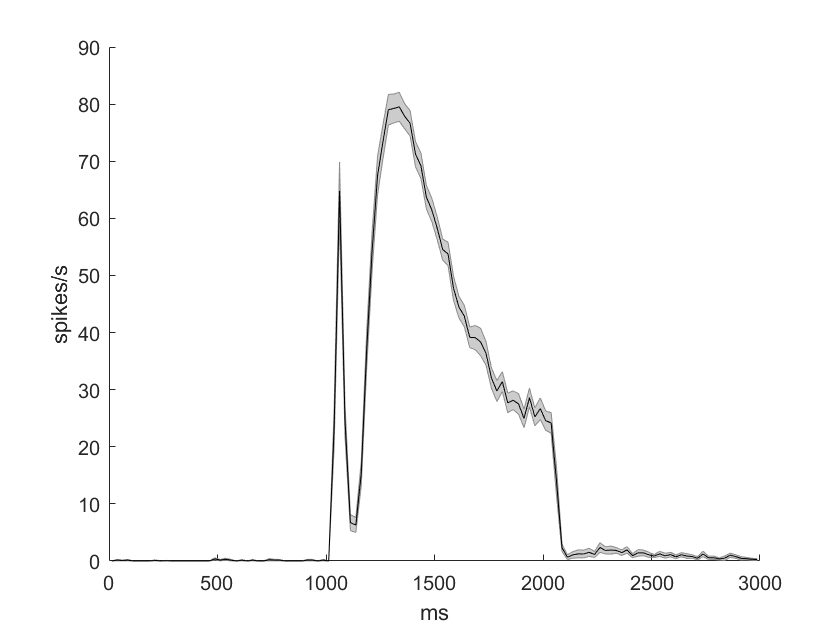


figure
shadedErrorBar([windowTime/2:windowTime:3000-windowTime/2], mean(psth_full), std(psth_full)/sqrt(size(psth_full, 2)))
xlabel('ms')
ylabel('spikes/s')

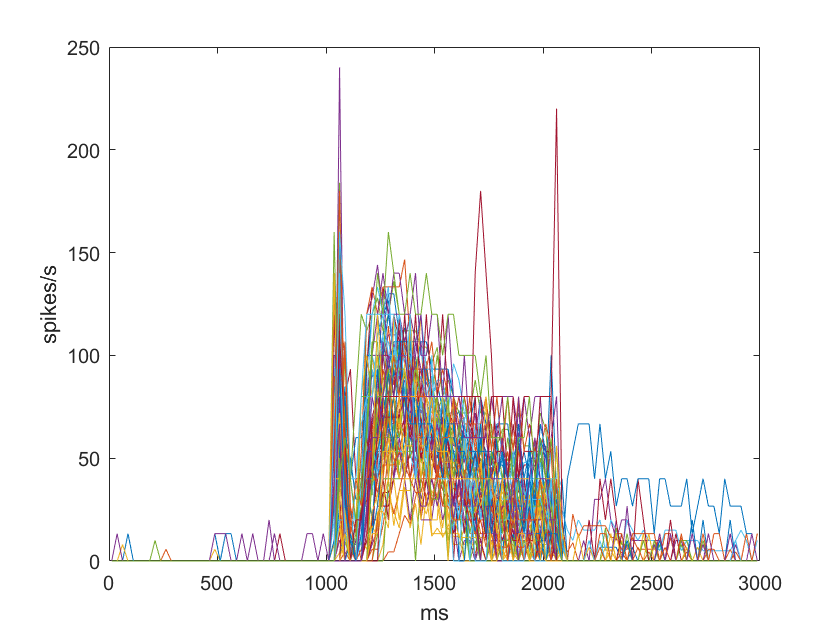


figure
plot([windowTime/2:windowTime:3000-windowTime/2], psth_full')
xlabel('ms')
ylabel('spikes/s')